# Actividad 8.1.2 (Modelado Cinemático de Piernas)

### Jhonatan Yael Martinez Vargas

### Instrucciones:

**Obtener** la matriz de  transformación **homogénea  T ** de los siguientes sistemas la cual relacione la posición y orientación del extremo del robot respecto a su sistema de referencia fijo (la base).

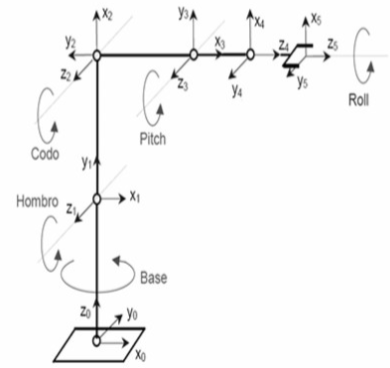

Dada la configuración propuesta en la imagen, lo primero que se debe de hacer es las matrices de transformación homogénea, para este caso se toma en cuenta que las longitudes ***"L1, L2," ***mediran 4 unidades, mientras que*** "L3, L4"  ***seran de  2 unidades.

clear all
close all
clc

%Calculamos las matrices de transformación homogénea
m_H0 = SE3

 

m_H0 = 
         1         0         0         0
         0         1         0         0
         0         0         1         0
         0         0         0         1


m_H1 = SE3(rotx(pi/2), [0,0,2])

 

m_H1 = 
         1         0         0         0
         0    0.9996   -0.0274         0
         0    0.0274    0.9996         2
         0         0         0         1


m_H2 = SE3(rotz(pi/2), [0,2,0])

 

m_H2 = 
    0.9996   -0.0274         0         0
    0.0274    0.9996         0         2
         0         0         1         0
         0         0         0         1


m_H3 = SE3(rotz(-pi/2), [0,-2,0])

 

m_H3 = 
    0.9996    0.0274         0         0
   -0.0274    0.9996         0        -2
         0         0         1         0
         0         0         0         1



% para la penultima articulacion se aplican dos rotaciones, una sobre el eje "b" y la otra sobre el eje "X" por lo que se separaran en 2 transformaciones diferentes:
m_H4 = SE3(rotz(pi/2), [0,0,0])

 

m_H4 = 
    0.9996   -0.0274         0         0
    0.0274    0.9996         0         0
         0         0         1         0
         0         0         0         1


m_H5 = SE3(rotx(pi/2), [0,-1,0])

 

m_H5 = 
         1         0         0         0
         0    0.9996   -0.0274        -1
         0    0.0274    0.9996         0
         0         0         0         1



m_H6 = SE3(roty(0), [0,0,1])

 

m_H6 = 
         1         0         0         0
         0         1         0         0
         0         0         1         1
         0         0         0         1


Posteriormente lo que se realiza es definir a las matrices de transformacion globales, las cuales son el resultado del producto de dos tramas.

%Matriz de transformación homogenea global de 6 a 0 
m_H20 = m_H1 * m_H2

 

m_H20 = 
    0.9996   -0.0274         0         0
    0.0274    0.9992   -0.0274     1.999
    0.0008    0.0274    0.9996     2.055
         0         0         0         1


m_H30 = m_H20 * m_H3

 

m_H30 = 
         1         0         0   0.05482
         0    0.9996   -0.0274 0.0007513
         0    0.0274    0.9996         2
         0         0         0         1


m_H40 = m_H30 * m_H4

 

m_H40 = 
    0.9996   -0.0274         0   0.05482
    0.0274    0.9992   -0.0274 0.0007513
    0.0008    0.0274    0.9996         2
         0         0         0         1


m_H50 = m_H40 * m_H5

 

m_H50 = 
    0.9996   -0.0274    0.0008   0.08224
    0.0274    0.9981   -0.0548   -0.9985
    0.0008    0.0548    0.9985     1.973
         0         0         0         1


m_H60 = m_H50 * m_H6

 

m_H60 = 
    0.9996   -0.0274    0.0008   0.08299
    0.0274    0.9981   -0.0548    -1.053
    0.0008    0.0548    0.9985     2.971
         0         0         0         1


Finalmente para temas de simulacion se establecen los limites del entorno en el cual se va deserrollar la simulación

plot3(0, 0, 0); axis([-6 6 -6 6 -6 6]); grid on;
hold on;

Se realizan las animaciones para cada una de las tramas:

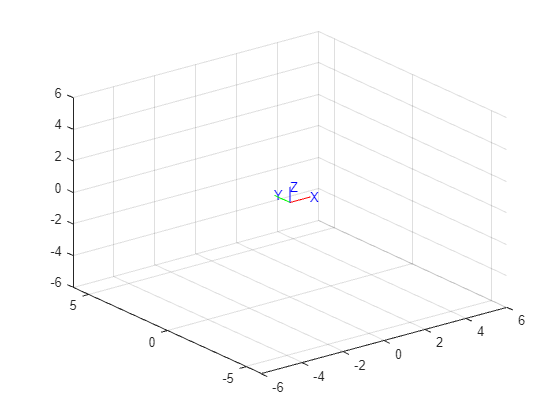

trplot(m_H0,'rgb','axis', [-6 6 -6 6 -6 6])

% Matriz de transformacion final
disp(m_H40)

       0.9996  -0.02741         0   0.05482
       0.0274    0.9992  -0.02741 0.0007513
    0.0007514    0.0274    0.9996         2
            0         0         0         1


Aqui lo que se puede apreciar es el valor numerico que representa la matriz de transformacion final